x =      1     2     3    -4     5     6


h =      0     1     2     3     4


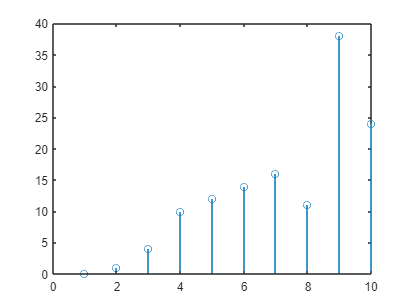

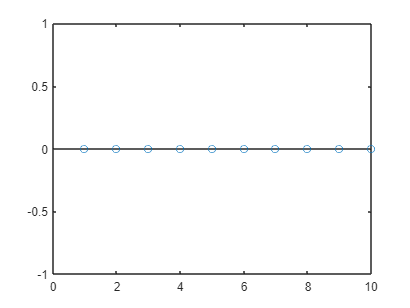

x=[1,2,3,-4,5,6]

h=[0,1,2,3,4]
n=length(h);
X=[x,zeros(1,length(h))];
H=[h,zeros(1,length(x))];
lenConvo=length(x)+length(h)-1;
con=zeros(1,lenConvo);
for i=1:lenConvo
    for j=1:length(x)
        if(i-j+1>0)
            con(i)=con(i)+X(j)*H(i-j+1);
        end
    end
end
stem(con);
stem(conv(x,h));
diff=con-conv(x,h);
stem(diff);
